app = actxserver(strcat('Designer.Application.','222'));


## 1.  JMAG Thermal Condition Interface

#### HTB : Heat Transfer Boundary 

    HTC : Heat Transfer Coefficient [W/m^2/degC]

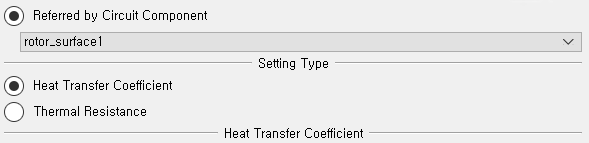

#### CTR : Contact Thermal Resistane

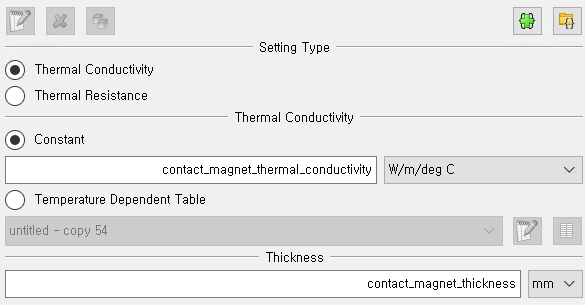

#### Initial Temp

#### Heat Source

% 우선 JCF로부터 Condition 가져오는듯 
app.GetModel(1).GetStudy(0).MergeJcf(directory.decode() + "/rotor/rotor-Case"+str(i+2)+".jcf")
app.GetModel(1).GetStudy(0).MergeJcf(directory.decode() + "/stator/stator-Case"+str(i+1)+".jcf")

app.GetModel(1).GetStudy(0).GetCondition("HTB_rotor_surface1").GetName()

%이름 변경 
%
app.GetModel(1).GetStudy(0).GetCondition("HTB_rotor_surfaceTest").SetName("HTB_rotor_surface1Test")

### HTC define

HTC_rtToAir            =        60  ;             
HTC_rtToGap            =        60  ;        
HTC_stToGap            =        60  ;        
HTC_stToAir            =        60  ;        
HTC_stToCover          =        60  ;          
HTC_coilToInsul        =        60  ;            
HTC_InsulToAir         =        60  ;

### Define Name

con_rtToAir            = 'rotorToAir'                 
con_rtToGap            = 'rotorToAir'          
con_stToGap            = 'rotorToAir'          
con_stToAir            = 'rotorToAir'          
con_stToCover          = 'rotorToAir'          
con_coilToInsul        = 'rotorToAir'          
con_InsulToAir         = 'rotorToAir'


RPM=2000    ;
poles =4    ;

## [TB]Face Select Algorithm

Jmag은 알고리즘안짜고 직접 선택하도록 함 

app.View().SetActiveSubWindowSize(569, 1198) app.View().SetCamera(89.4748840332031, 28.2280597686768, 152.69580078125, 20.9087295532227, 20.9087295532227, 10.9385070800781, 0.253789275884628, 0.95186173915863, -0.171901881694794, 63.0555572509766, 63.0555572509766) app.View().SelectWorldPos(7.5840864181518555, 27.085166931152344, 17.064559936523438, 0) app.View().SelectWorldPos(7.154862403869629, 26.65746307373047, 17.294254302978516, 0) app.View().SelectFace() app.View().SelectWorldPos(4.668300628662109, 27.18257713317871, 18.469858169555664, 0) app.View().SelectWorldPos(7.070270538330078, 26.340194702148438, 17.351552963256836, 0) app.GetModel("devThermal_12").GetSetList().CreateFaceSet("rotor core to gap") app.GetModel("devThermal_12").GetSetList().GetSet("rotor core to gap").SetUpdateByRelation(False) app.GetModel("devThermal_12").GetSetList().GetSet("rotor core to gap").SetMatcherType("Selection") app.GetModel("devThermal_12").GetSetList().GetSet("rotor core to gap").ClearParts() sel = app.GetModel("devThermal_12").GetSetList().GetSet("rotor core to gap").GetSelection() sel.SelectFace(506) app.GetModel("devThermal_12").GetSetList().GetSet("rotor core to gap").AddSelected(sel)

## 2. [TB]EM 3D Setting

### Add Shaft

### Add Cover

### 3D extend

CurrentModel=app.GetCurrentModel()
CurrentModel.GetName()
CurrentModel.RestoreCadLink(1)
CurrentModel.ExtendTo3DSolid(130,1)
CurrentModel.UpdateCadModel(1)
% CurrentModel.UpdateCadModel(1)
% app.GetModel("devThermal_2").RestoreCadLink(1)
% app.GetModel("devThermal_2").ExtendTo3DSolid(130, 1)
% app.GetModel("devThermal_2").UpdateCadModel(1)
app.GetModel("devThermal_4").ClearMeshGroupSettingAllStudies()

### Iron Loss Settting


setIronLoss=CurrentModel.GetStudy("Express Project").CreateCondition("Ironloss", "Iron loss")

setIronLoss.AddPart('Stator Core')
setIronLoss.AddPart('Rotor Core')


setIronLoss.SetValue("RevolutionSpeed", RPM)
setIronLoss.SetValue("Poles", poles)

## 3.Thermal 3D Study setting (Steady)

누가 좀 해줘

이틀 전체 글 쓰고 (일, 토)

Model3D=app.GetCurrentModel()
Model3D.GetName()


### Create Study (From Transient Magnet)

Steady=Model3D.CreateStudy('HeatSteady','HeatSteady')



### Set Circuit

#### Define Link List

% get circuit link list to Struct 
SteadyCircuit=Steady.GetCircuit()

% 
NumComponents=SteadyCircuit.NumComponents()
for i=1:NumComponents
    strSteady.Circuit(i).Name=SteadyCircuit.GetComponent(i-1).GetName()
    strSteady.Circuit(i).Type=SteadyCircuit.GetComponent(i-1).GetType()
end    

NumInstances=SteadyCircuit.NumInstances()
for i=1:NumInstances
    SteadyCircuit.GetComponentInstance(i-1).GetName()
    SteadyCircuit.GetComponentInstance(i-1).GetType()
end  
SteadyCircuit.NumComponentsByType('HeatTransfer')


#### Set Circuit  Compoent & Instance 

newCircuit=Steady.CreateCircuit()
app.GetModel("IPM-ACLoss").GetStudy("HeatSteady").GetCircuit().CreateComponent("HeatTransfer", "T2")

for i=1:NumComponents
    ComponentType=strSteady.Circuit(i).Type;
    ComponentName=strSteady.Circuit(i).Name;
    newCircuit.CreateComponent(ComponentType,ComponentName)
    x=i*5
    y=i*5
    newCircuit.CreateInstance(ComponentName,x,y)
end

### Set Condition 

GroupName='StCore'

#### [JAC018]Set setList and set Info

setList=Model3D.GetSetList()
numSet=setList.NumSet()
for i=1:numSet
    set=    setList.GetSet('Magnet Region1')
    set.GetName()
end
selGroup=condComponentName.GetSelectionByGroup()


#### [WIP] JFT154Create  Condition From JCF

% Assuming 'app' is an object with methods and properties in MATLAB (similar to Python)
app.SetCurrentStudy(1);

% Rotor 
for i = 1:(poles - 1)
    app.GetModel(1).GetStudy(0).MergeJcf([char(directory), '/rotor/rotor-Case', num2str(i + 2), '.jcf']);
    
    app.GetModel(2).GetStudy(0).GetCondition('HTB_rotor_surface').SetName(['HTB_rotor_surface', num2str(i + 2)]);
    app.GetModel(2).GetStudy(0).GetCondition('HTB_rotor_gap').SetName(['HTB_rotor_gap', num2str(i + 2)]);
    app.GetModel(2).GetStudy(0).GetCondition('HTB_rotor_low').SetName(['HTB_rotor_low', num2str(i + 2)]);
    app.GetModel(2).GetStudy(0).GetCondition('HTB_rotor_shaft').SetName(['HTB_rotor_shaft', num2str(i + 2)]);
    
    app.DeleteModel(1);
end

% stator
for i = 1:slots
    app.GetModel(1).GetStudy(0).MergeJcf([char(directory), '/stator/stator-Case', num2str(i), '.jcf']);
    %% Stator Core
    app.GetModel(2).GetStudy(0).GetCondition('HTB_stator_up').SetName(['HTB_stator_up', num2str(i)]);
    app.GetModel(2).GetStudy(0).GetCondition('HTB_stator_side_up').SetName(['HTB_stator_side_up', num2str(i)]);
    app.GetModel(2).GetStudy(0).GetCondition('HTB_stator_side_low').SetName(['HTB_stator_side_low', num2str(i)]);
    app.GetModel(2).GetStudy(0).GetCondition('HTB_stator_low').SetName(['HTB_stator_low', num2str(i)]);
    %% Coil
    app.GetModel(2).GetStudy(0).GetCondition('HTB_coil_up1').SetName(['HTB_coil_up1', num2str(i)]);
    app.GetModel(2).GetStudy(0).GetCondition('HTB_coil_low1').SetName(['HTB_coil_low1', num2str(i)]);
    app.GetModel(2).GetStudy(0).GetCondition('HTB_coil_up2').SetName(['HTB_coil_up2', num2str(i)]);
    app.GetModel(2).GetStudy(0).GetCondition('HTB_coil_low2').SetName(['HTB_coil_low2', num2str(i)]);
    %% Gap
    app.GetModel(2).GetStudy(0).GetCondition('HTB_stator_gap').SetName(['HTB_stator_gap', num2str(i)]);
end


#### [JAC018]Create Boundary Condition with SetList & circuit link list


for i=1:NumComponents
    ComponentType=strSteady.Circuit(i).Type;
    ComponentName=strSteady.Circuit(i).Name;
    if strcmp(ComponentType,'Heat Transfer Boundary')==1
        condComponentName=Steady.CreateCondition('HeatTransfer',ComponentName)
        condComponentName.SetLink(ComponentName)
        condComponentName.SetValue("RefTemperatureType", 1)
        condComponentName.SetValue("Coefficient", HTC_rtToGap)
%         condComponentName.AddSelected(sel)
        
        set=    setList.GetSet('StCore')  %% TB
        setName=set.GetName()
        condComponentName.AddSet(set,0)
    end
end

    % 
    % %
    % 
    % rtToGap=Steady.CreateCondition('HeatTransfer',con_stToGap)
    % rtToGap.SetLink("rotor core to gap")
    % rtToGap.SetValue("RefTemperatureType", 1)
    % rtToGap.SetValue("Coefficient", HTC_rtToGap)
    % 
    % sel=rtToGap.GetSelection()
    % sel.SelectFace(506)
    % rtToGap.AddSelected(sel)

% for 


#### Set Periodic Boundary

#### [OW] Heat Source 

idea : 자주쓰는 코드는 함수화 해놓고, 입력받아서 설정

LossPartName(i).Name

JouleLossSource= Steady.CreateCondition('HeatGeneration','CopperLoss')
JouleLossSource.SetValue("GenerationType", 4)
JouleLossSource.SetValue("ConstantScale", 0.25)
JouleLossSource.SetValue("UseLossAverage", 1)
JouleLossSource.SetValue("StartStep", 1)
JouleLossSource.SetValue("ReferenceLossFile_DataSourceType", 2)
JouleLossSource.SetValue("ReferenceLossFile_CurrentProject_StudyId", 6)
JouleLossSource.SetCoordinateSystem("ReferenceLossFile_CoordinateId", "Global Rectangular")
JouleLossSource.ClearParts()


sel =JouleLossSource.GetSelection()
sel.SelectPart(86)
JouleLossSource.AddSelected(sel)

#### Contact Resistance

ContactR    = Steady.CreateCondition("Contact Resistance", "ContactRMag")
ContactR.SetValue("SettingType", 1)
ContactR.SetValue("ThermalResistance", 10)
ContactR.ClearParts()


sel = ContactR.GetSelection()
sel.SelectFace(519)
ContactR.AddSelected(sel)


% Coil Contact Resistance
ContactRCoil=Steady.CreateCondition("CustomContactResistance", "CoilToCore")
ContactRCoil.SetValue("InsulationThickness", 0.05)
ContactRCoil.SetValue("WireDiameter", 0.8)
ContactRCoil.SetValue("FillFactor", 49)
ContactRCoil.SetValue("ImpregnationType", 1)
ContactRCoil.SetValue("ConductorLength", 4)

ContactRCoil.ClearParts()
sel = ContactRCoil.GetSelection()
sel.SelectFace(33)
ContactRCoil.AddSelected(sel)

## 4.Solver Setting

#### Step Control

#### Linear Setting

#### Nonlinear Setting



app.GetModel("devThermal_12").GetStudy("steady state 7").GetCondition("untitled 1").SetCoordinateSystem("FileName_CoordinateId", "Global Rectangular")

AddPart('Stator Core')

sel = app.GetModel("devThermal_12").GetStudy("steady state 7").GetCondition("untitled 1").GetSelection()
sel = app.GetModel("devThermal_12").GetStudy("steady state 7").GetCondition("untitled 1").GetSelection()
sel.SelectFace(506)
app.GetModel("devThermal_12").GetStudy("steady state 7").GetCondition("untitled 1").AddSelected(sel)

Transient

### Initial Temp

Transient=CurrentModel.GetStudy("transient 8")
setInitialTemp=Transient.CreateCondition("InitialTemperature", "Initial")

setInitialTemp.ClearParts()
sel = setInitialTemp.GetSelection()
sel.SelectFace(507)
setInitialTemp.AddSelected(sel)

